# What’s the benefit of a string array over a cell array?

In [a Reddit thread](https://www.reddit.com/r/matlab/comments/x82du2/how_to_join_strings_to_make_a_vector_for_the/) where I recommending using [string](https://www.mathworks.com/help/matlab/ref/string.html), [u/Lysol3435](https://www.reddit.com/u/Lysol3435/)/ asked me "**What’s the benefit of a string array over a cell array?**"

My quick answer: string arrays are more powerful because it is designed to handle text better, and I promised to do another code share. I am going to repurpose [the code](https://blogs.mathworks.com/loren/2016/09/15/introducing-string-arrays/) I wrote a few years ago to show what I mean.

Bottom line on top

- strings enables cleaner, easier to understand code, no need to use `strcmp`, `cellfun` or `num2str`.

- strings are more compact

- string-based operations are faster

At this point, *for text handling*, I can't think of any good reasons to use cell arrays.

## String Construction

This is how you create a cell array of string.

myCellstrs = {'u/Creative_Sushi','u/Lysol3435',''};

This is how you create a string array.

myStrs = ["u/Creative_Sushi","u/Lysol3435",""];

So far no striking differences in syntax, just quotes vs double quotes and angled vs curly brackets.

## String comparison

Lets compare two strings. Here is how you do it with a cell array. This returns 0 (false):

isSameCell = strcmp(myCellstrs(1),myCellstrs(2));

Here is how you do it with a string array. Much shorter and easier to understand.

isSameStr = myStrs(1) == myStrs(2);

## Find empty element

With a cell array, you need to use `cellfun`. This returns [0 0 1]:

isEmptyCell = cellfun(@isempty, myCellstrs);

With a string array, it is shorter and easier to understand.

isEmptyStr = myStrs == "";

## Use math like operations

With strings, you can use other operations besides ==. For example, to create 'myfile1.txt', instead of this

filenameCell = ['myfile', num2str(1), '.txt'];

You can do this, and numeric values will be automatically converted to text.

filenameStr = "myfile" + 1 + ".txt";

## Use array operations

You can also use it like a regular array. This will create an 5x1 vector of "Reddit" repeated in every row.

arr = repmat("Reddit",5,1);

## No need to use loop

Let's use [Popular Baby Names](https://www.ssa.gov/oact/babynames/limits.html) dataset. I downloaded it and unzipped into a folder named "names". Inside this folder are text files named 'yob1880.txt' through 'yob2021.txt'.

If you use a cell array, you need to use a for loop.

years = (1880:2021);
fnames_cell = cell(1,numel(years));
for ii = 1:numel(years)
    fnames_cell(ii) = {['yob' num2str(years(ii)) '.txt']};  
end

If you use a string array, it is much simpler.

fnames_str = "yob" + years + ".txt";

## Use case example - loading data from multiple files

Now let's load the files one by one and concatenate everything into a table using various string operations. You can do this without a loop if you use [datastore](https://www.mathworks.com/help/matlab/datastore.html) - check out the appendix. 

names = cell(numel(years),1);                    % pre-allocate a cell array
vars = ["name","sex","births"];                  
for ii = 1:numel(fnames_str)
    filename = "names/" + fnames_str(ii);        % use math operation
    tbl = readtable(filename,TextType="string");
    tbl.Properties.VariableNames = vars;
    tbl.year = repmat(years(ii),height(tbl),1);  % use array operation
    names{ii} = tbl;
end
names = vertcat(names{:});                       % concatenate tables into one table
head(names)

       name        sex    births    year
    ___________    ___    ______    ____

    "Mary"         "F"     7065     1880
    "Anna"         "F"     2604     1880
    "Emma"         "F"     2003     1880
    "Elizabeth"    "F"     1939     1880
    "Minnie"       "F"     1746     1880
    "Margaret"     "F"     1578     1880
    "Ida"          "F"     1472     1880
    "Alice"        "F"     1414     1880



## Compare the size of variables

Let's compare the number of bytes - the string array uses 1/2 of the memory used by the cell array.

namesString = names.name;            % this is string
namesCellAr = cellstr(namesString);  % convert to cellstr
whos('namesString', 'namesCellAr')   % check size and type

  Name                   Size                Bytes  Class     Attributes

  namesCellAr      2052781x1             238812080  cell                
  namesString      2052781x1             116357742  string              



## Compare the speed

String arrays also comes with new methods. Let's compare `strrep` vs. `replace`. Took only 1/3 of time with string array.

tic, strrep(namesCellAr,'Joey','Joe'); toc, % time strrep operation

Elapsed time is 0.693350 seconds.


tic, replace(namesString,'Joey','Joe'); toc, % time replace operation

Elapsed time is 0.237445 seconds.


## Let's play with strings

Let's plot a subset of data

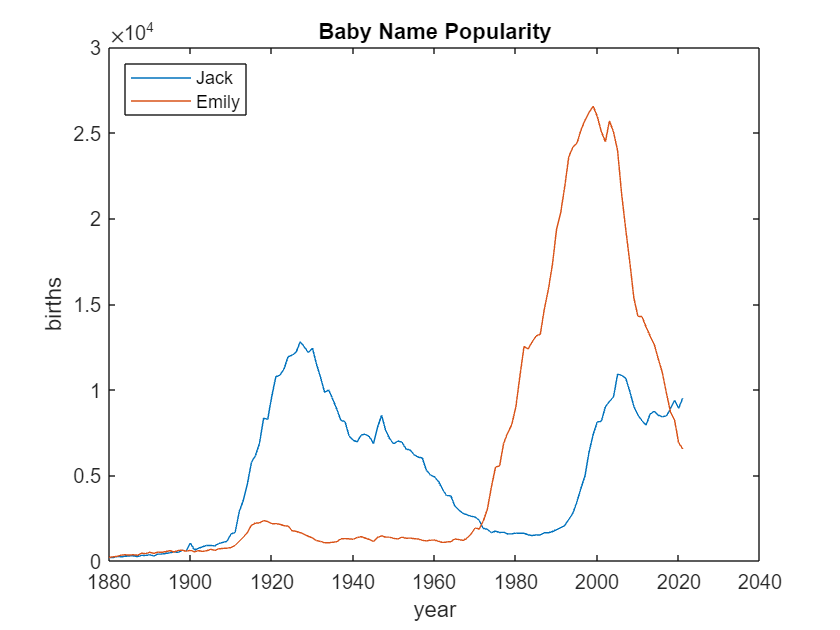

Jack = names(names.name == 'Jack', :);   % rows named 'Jack' only
Emily = names(names.name == 'Emily', :); % rows named 'Emily' only
Emily = Emily(Emily.sex == 'F', :);      % just girls
Jack = Jack(Jack.sex == 'M', :);         % just boys
figure 
plot(Jack.year, Jack.births); 
hold on
plot(Emily.year, Emily.births); 
hold off
title('Baby Name Popularity');
xlabel('year'); ylabel('births');
legend('Jack', 'Emily', 'Location', 'NorthWest') 

Now let's create a word cloud from the 2021 data.

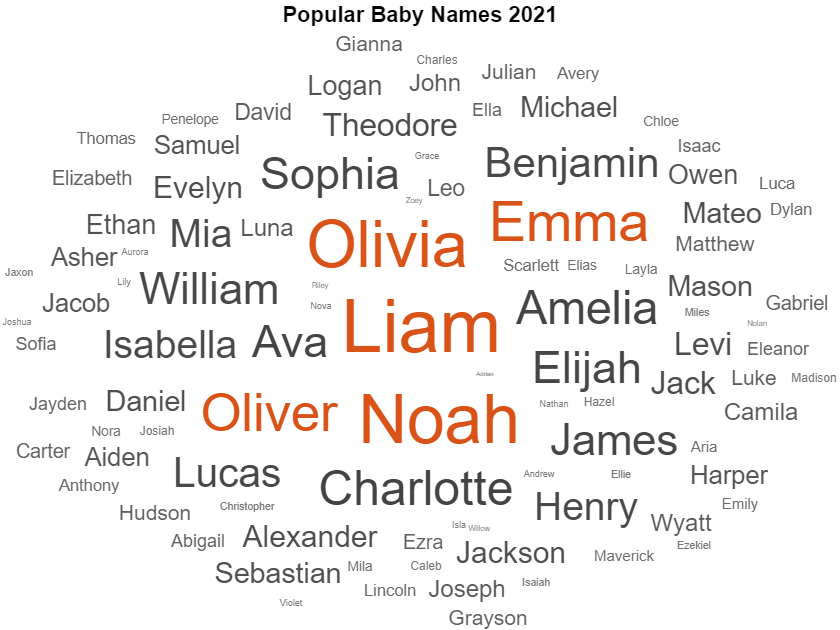

figure
wordcloud(names.name(names.year == 2021),names.births(names.year == 2021)) 
title("Popular Baby Names 2021")

## Appendix

### Using datastore to load data from multiple files

Earlier we used a loop to load data from multiple files. Here is how you do the same using datastore.

loc = "names/*.txt";
vars = ["name","sex","births"];
ds = datastore(loc,VariableNames=vars,TextType="string");
ds = transform(ds, @addYearToData, 'IncludeInfo', true); % use helper function
names = readall(ds);
head(names)

       name        sex    births    year
    ___________    ___    ______    ____

    "Mary"         "F"     7065     1880
    "Anna"         "F"     2604     1880
    "Emma"         "F"     2003     1880
    "Elizabeth"    "F"     1939     1880
    "Minnie"       "F"     1746     1880
    "Margaret"     "F"     1578     1880
    "Ida"          "F"     1472     1880
    "Alice"        "F"     1414     1880



Helper function to extract years from the filenames

function [data, info] = addYearToData(data, info)
    [~, filename, ~] = fileparts(info.Filename);
    data.year(:, 1) = str2double(erase(filename,"yob"));
end